clear;close all
n=1000;p=1;m=100;
xx=Tent_x(n,p);
%xx=Logistic_x(4,n,p);
%[~,~,U,K,~,x_marker] = Tent_U_Rectangle_leftU(xx,m);
[~,~,U,K,~,x_marker] = Tent_U_Gauss_leftU(xx,m);

A=U';
% A=[.5,.5,0,0;0,0,.5,.5;0,0,.5,.5;.5,.5,0,0];
[mm,nn]=size(A);
lambda=0;
miu=0.1;N=1;
f=@(x)norm(A*x-lambda*x)+miu*norm(diff(x),N);
nonlcon=@con;
options=optimoptions(@fmincon,'MaxFunEvals',10000,'Algorithm','sqp');
[x,fval,exitflag,~] = fmincon(f,2*rand(mm,1),[],[],[],[],[],[],nonlcon,options);


Solver stopped prematurely.

fmincon stopped because it exceeded the function evaluation limit,
options.MaxFunctionEvaluations = 10000 (the selected value).



% [x,fval,exitflag,~] = fmincon(f,[sin(2*pi*linspace(1,0,mm)')],[],[],[],[],[],[],nonlcon,options);
N1=norm(A*x-lambda*x,2)

N1 = 0.0250

% N2=norm(A*[.5;.5;-.5;-.5]-lambda*x,2) suiji tidu suanfa 1.initial condition 2.norm 3.local minimum
D1=norm(diff(x),N)

D1 = 0.9039

% D2=norm(diff([.5,.5,-.5,-.5]),pp)
F1=f(x)

F1 = 0.1154

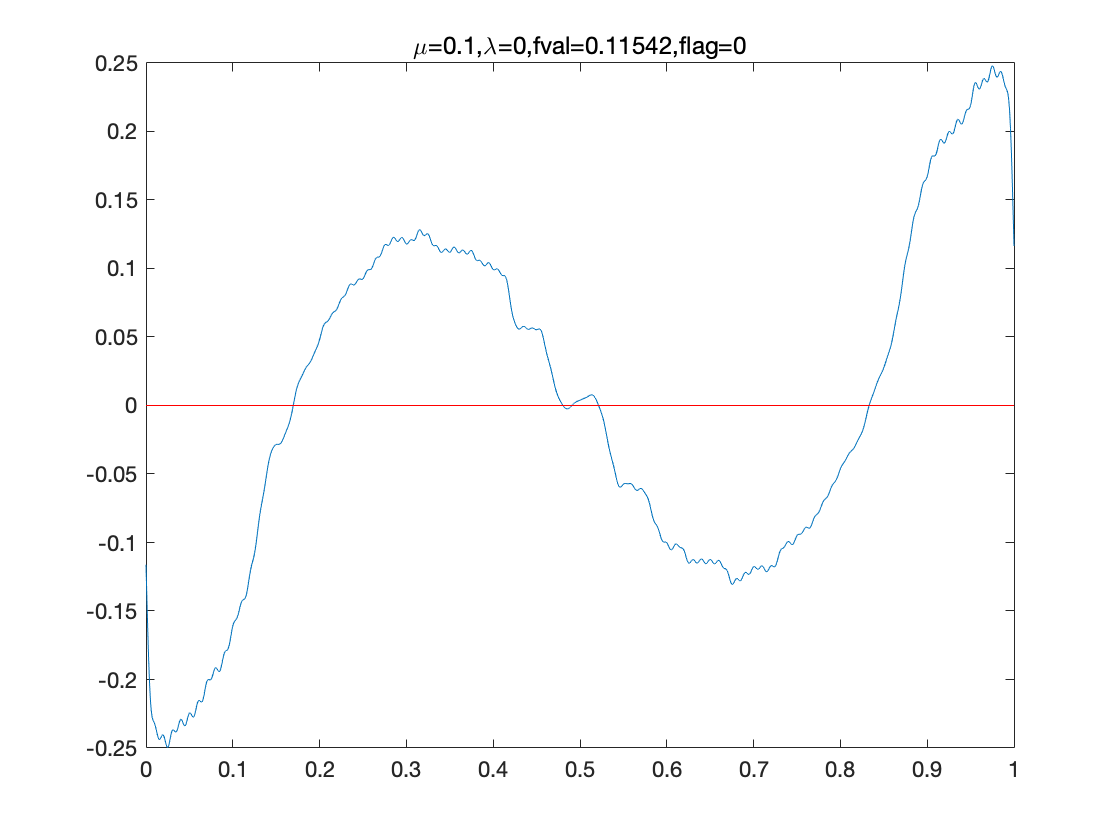

% F2=f([.5;.5;-.5;-.5])

pA=real(K*x);
figure
% subplot(121)
%set(gcf,'outerposition',get(0,'screensize'));
x0=linspace(0,1,n);
hh=plot(x0,pA);
hold on
plot([0,1],[0,0],'r')
title(['\mu=',num2str(miu),',\lambda=0,fval=',num2str(fval),',flag=',num2str(exitflag)])


f2=@(xx)norm(A*A*xx-lambda*xx)+miu*norm(abs(diff(xx)),N);
nonlcon2=@con;
[x2,fval2,exitflag2,~] = fmincon(f2,2*rand(mm,1),[],[],[],[],[],[],nonlcon2,options);


Solver stopped prematurely.

fmincon stopped because it exceeded the function evaluation limit,
options.MaxFunctionEvaluations = 10000 (the selected value).



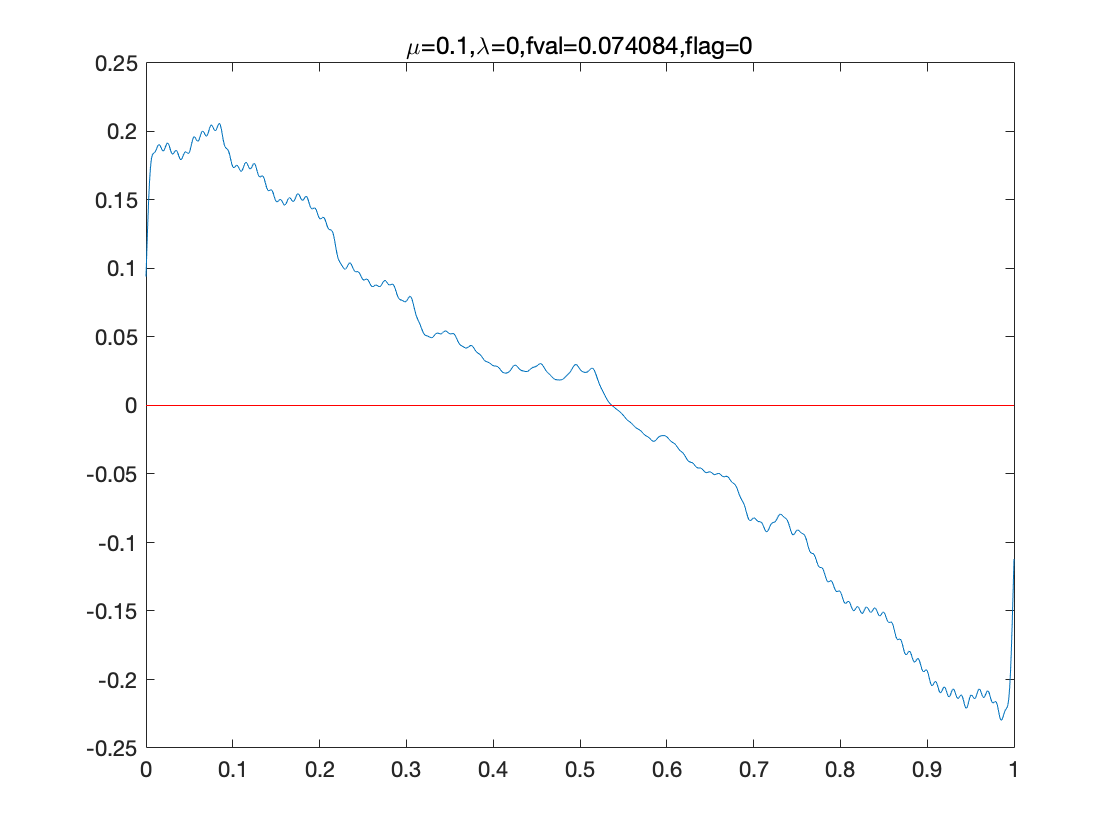


pA2=real(K*x2);
% subplot(122)
figure
%set(gcf,'outerposition',get(0,'screensize'));
x0=linspace(0,1,n);
hh=plot(x0,pA2);
hold on
plot([0,1],[0,0],'r')
title(['\mu=',num2str(miu),',\lambda=0,fval=',num2str(fval2),',flag=',num2str(exitflag2)])

function [c,ceq] = con(x)
% c(1) = x(1)+0.01;
% c(2) =x(2)+0.01;
% c(3)=-x(3)+0.01;
% c(4)=-x(4)+0.01;
c=[];
ceq = norm(x)-1;
end